##################################                  ##################################

##              MATLAB 数学实验A              ##                  ##              YHK-COPYRIGHT                ##

##             since 2024 May 21st              ##                  ##   B23042424 袁浩宽 MatlabR2024a  ##

##################################                  ##################################

                                                     -------------  特别提示  -------------

1.阅读本份实验报告之前，请在MatlabR2024a环境下首先将实时脚本全部运行一遍，以确保每一张图都可被画出，每一个结果或公式都会被打印出来。

2.首次运行该实时脚本的时间约为40秒，请耐心等待。（但如果发现文件打开后就有图片等就不用运行）

3.本脚本在运行过程中会出现较多警告，忽略即可，不影响最终答案的输出。

4.警告的主要原因是一些算法或者表达式Matlab认为效率不够高或精度不够高。

                                                    -------------  特别注意  -------------

在下面的题目中，1-4班m为你学号的后3位，00班 m为你学号的后2位+70

在此有：

m = 424;

###########################

#######    SECTION 1   #######

###########################

1.

(1)

syms x;
limit_0 =limit((sqrt(1+m*x^2)-cos(m*x))/x^2);
disp(limit_0);

$$90100$$

(2)

limit_1 = limit((sqrt(1 + m*x^2)-cos(m*x))/x,x,Inf);
disp(limit_1)

$$\sqrt{424}$$

2.

(1)

v1 = int(exp(-m*x^2),x,0,Inf);
disp(v1);

$$\frac{\sqrt{106}\,\sqrt{\pi }}{424}$$

(2)

v2 = int(exp(x^2),x,0,1/2);
disp(v2);

$$\frac{\sqrt{\pi }\,\mathrm{erfi}\left(\frac{1}{2}\right)}{2}$$

(3)

v3 = int((m*x^4)/(25 + 4*x^2));
disp(v3);

$$\frac{6625\,\mathrm{atan}\left(\frac{2\,x}{5}\right)}{4}-\frac{1325\,x}{2}+\frac{106\,x^{3}}{3}$$

(4)

syms y;
v4 = int(int(sqrt(1-x^2),y,-sqrt(1-x^2),sqrt(1-x^2)),x,-1,1);
disp(v4);

$$\frac{8}{3}$$

(5)

v5 = int(exp(-abs(x))*abs(sin(x)),x,-3*pi,1.6*pi);
disp(vpa(v5,64));

$$1.086229283558525811440413924347348147077977176807481700165368465$$

3.

前20项展开对应的20条曲线如下：

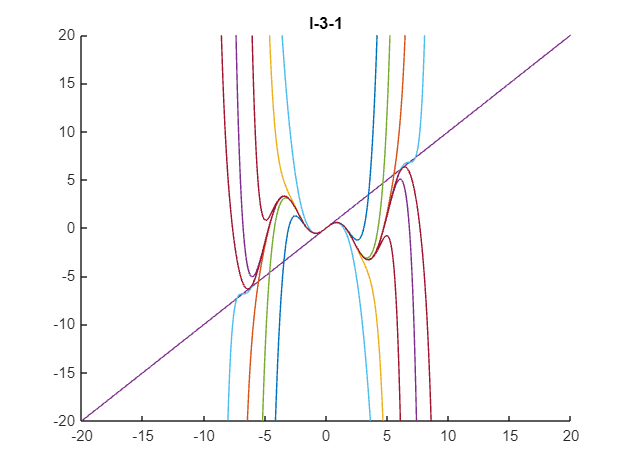

syms x_sym; 
f = x_sym * cos(x_sym); 
x_values = -20*pi:0.01:20*pi; 

hold on; 
for i = 1:20
    taylor_exp = taylor(f, x_sym, 'Order', i); 
    taylor_func = matlabFunction(taylor_exp, 'Vars', x_sym); 
    y_values = taylor_func(x_values); 
    plot(x_values, y_values); 
end
xlim([-20 20]);
ylim([-20 20]);
title('I-3-1');
hold off; 

% 由于部分函数值较大，已将图像x,y轴区域规定在一定范围内。

原函数曲线如下：

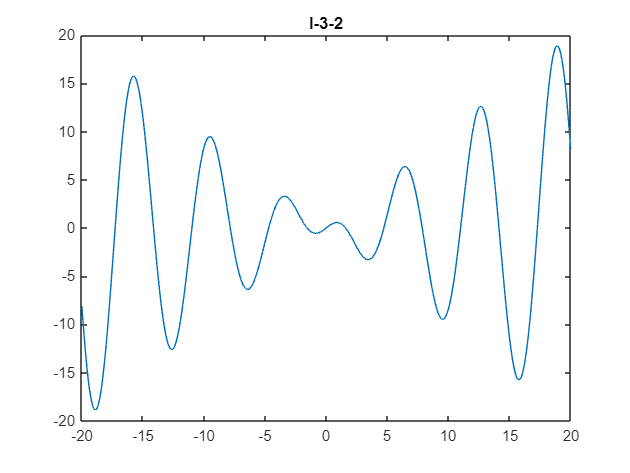

plot(x_values,x_values.*cos(x_values));
xlim([-20 20]);
ylim([-20 20]);
title('I-3-2');

4.

(1)

M = 0;
s = 0;
for n = 2:10000
    s = s + 1/(sqrt(n)*log(n));
    if s > 10
        M = n;
        break;
    end
end
disp(M);

   333



(2)

n = 1:1000;
s = sum(n.*sin(n)./(2.^n));
disp(s);

    0.6265



5.

(1)

syms x;
y = exp(x)*cos((m/100)*x^2 + x + 1);
disp(y);

$${\mathrm{e}}^{x}\,\cos\left(\frac{106\,x^{2}}{25}+x+1\right)$$

disp(diff(y,x,2));

$$\begin{array}{l} {\mathrm{e}}^{x}\,\sigma_{1}-\frac{212\,{\mathrm{e}}^{x}\,\sigma_{2}}{25}-{\mathrm{e}}^{x}\,\sigma_{1}\,{\left(\frac{212\,x}{25}+1\right)}^{2}-2\,{\mathrm{e}}^{x}\,\sigma_{2}\,\left(\frac{212\,x}{25}+1\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{106\,x^{2}}{25}+x+1\right)\\ \sigma_{2}=\sin\left(\frac{106\,x^{2}}{25}+x+1\right) \end{array}$$

disp(subs(diff(y,x,10),x,0));

$$-\frac{192105798209248\,\sin\left(1\right)}{1953125}$$

(2)

syms y;
z = x^2*exp(-y);
disp(z);

$$x^{2}\,{\mathrm{e}}^{-y}$$

disp(subs(subs(diff(diff(z),x),x),x,1),y,2);

$$2\,{\mathrm{e}}^{-1}$$

disp(subs(subs(diff(diff(z),x),y),x,1),y,2);

$$2\,{\mathrm{e}}^{-y}$$

6.

A = [4 -2 2;-3 0 5;1 5 0.1*m];
B = [1 3 4;-2 0 -3;2 -1 1];
disp(det(A));

 -394.4000



disp(det(B));

    -7



disp(inv(A));

    0.0634   -0.2404    0.0254
   -0.3352   -0.4249    0.0659
    0.0380    0.0558    0.0152



disp(inv(B));

    0.4286    1.0000    1.2857
    0.5714    1.0000    0.7143
   -0.2857   -1.0000   -0.8571



[q,w] = eig(A)

q =     0.8803   -0.3598    0.0451
   -0.4728   -0.9261    0.1122
    0.0398    0.1130    0.9927


w =     5.1646         0         0
         0   -1.7755         0
         0         0   43.0109


[q2,w2] = eig(B)

q2 =    -0.0566    0.2637   -0.8195
    0.7886    0.7861    0.0395
   -0.6123   -0.5591    0.5718


w2 =     2.4728         0         0
         0    1.4626         0
         0         0   -1.9354


syms n;
[N,D] = eig(A);
disp(vpa(N*D^n/N,2));

$$\left(\begin{array}{ccc} 0.83\,5.2^{n}+7.5e-4\,43.0^{n}+0.17\,{\left(-1.8\right)}^{n} & 5.2e-3\,43.0^{n}-0.32\,5.2^{n}+0.32\,{\left(-1.8\right)}^{n} & 0.045\,43.0^{n}-1.3e-3\,5.2^{n}-0.044\,{\left(-1.8\right)}^{n}\\ 1.9e-3\,43.0^{n}-0.44\,5.2^{n}+0.44\,{\left(-1.8\right)}^{n} & 0.17\,5.2^{n}+0.013\,43.0^{n}+0.81\,{\left(-1.8\right)}^{n} & 6.7e-4\,5.2^{n}+0.11\,43.0^{n}-0.11\,{\left(-1.8\right)}^{n}\\ 0.037\,5.2^{n}+0.017\,43.0^{n}-0.054\,{\left(-1.8\right)}^{n} & 0.11\,43.0^{n}-0.015\,5.2^{n}-0.099\,{\left(-1.8\right)}^{n} & 0.99\,43.0^{n}-5.7e-5\,5.2^{n}+0.014\,{\left(-1.8\right)}^{n} \end{array}\right)$$

disp(A/B);

         0         0    2.0000
   -2.7143   -8.0000   -8.1429
   -8.8286  -36.4000  -31.4857



disp(A\B);

    0.5948    0.1648    1.0000
    0.6466   -1.0715         0
   -0.0431    0.0989         0



7.

a1 = [-5 -1 -5 -1 5]';
a2 = [-2 2 -10 2 10]';
a3 = [-3 3 -5 3 5]';
a4 = [0 1 -1 1 1]';
a5 = [-1 1 -11 1 11]';
mat = [a1 a2 a3 a4 a5];
disp(rref(mat));

    1.0000         0         0   -0.1667         0
         0    1.0000         0    0.0667    1.4000
         0         0    1.0000    0.2333   -0.6000
         0         0         0         0         0
         0         0         0         0         0



由题意可知，a1,a2,a3为极大无关组，其中

a4 =  `- 0.1667a1 + 0.0667a2 + 0.2333a3`

a5 =                            `1.4000a2 - 0.6000a3`

8.

(1)

由题意得二次型系数矩阵：

M = [4 11/2 0 0 0;
 11/2 4 11/2 0 0;
 0 11/2 4 11/2 0;
 0 0 11/2 4 11/2;
 0 0 0 11/2 4]

M =     4.0000    5.5000         0         0         0
    5.5000    4.0000    5.5000         0         0
         0    5.5000    4.0000    5.5000         0
         0         0    5.5000    4.0000    5.5000
         0         0         0    5.5000    4.0000


[A,B] = eig(M);

正交变换矩阵：

disp(A);

    0.2887   -0.5000    0.5774    0.5000   -0.2887
   -0.5000    0.5000   -0.0000    0.5000   -0.5000
    0.5774   -0.0000   -0.5774   -0.0000   -0.5774
   -0.5000   -0.5000    0.0000   -0.5000   -0.5000
    0.2887    0.5000    0.5774   -0.5000   -0.2887



标准二次型：

syms x;
f_ = sum((ones(1,5)*x).^(1:5).*diag(B)');
disp(f_);

$$\frac{7614618381628597\,x^{5}}{562949953421312}+\frac{19\,x^{4}}{2}+4\,x^{3}-\frac{3\,x^{2}}{2}-\frac{3111018754258103\,x}{562949953421312}$$

(2)

solution1：

A = [1 2 -3 -1;   
     2 -1 -1 4;
     1 4 -7 -5];
B = [1; 4; -1];

先对系数矩阵和增广矩阵的秩进行比较：

disp(rank([A B]));

     3



disp(rank(A));

     3



比较结果可知，秩相同，有解。

再对增广矩阵做初等行变换得到行最简矩阵如下：

C = rref([A B]);
disp(C);

    1.0000         0         0    2.2000    2.4000
         0    1.0000         0   -0.4000    0.2000
         0         0    1.0000    0.8000    0.6000



得通解如下：

syms k1;
f = [-C(:,4);1]*k1 + [C(:,5);0];
disp(f)

$$\left(\begin{array}{c} \frac{12}{5}-\frac{11\,k_{1}}{5}\\ \frac{2\,k_{1}}{5}+\frac{1}{5}\\ \frac{3}{5}-\frac{4\,k_{1}}{5}\\ k_{1} \end{array}\right)$$

solution2：

A = [1 2 -3 -1;   
     2 -1 -1 4;
     1 4 -7 -5];
B = [1; 4; -1];

先求出特解b:

b = A\B

b =          0
    0.6364
   -0.2727
    1.0909


再求正交规范基：

null(A,'r')

ans =    -2.2000
    0.4000
   -0.8000
    1.0000


由上可知解空间维度为1，设基向量a:

a = null(A,'r');

则通解可以表示为：

syms k2;
f = a*k2 + b;
disp(f);

$$\left(\begin{array}{c} -\frac{11\,k_{2}}{5}\\ \frac{2\,k_{2}}{5}+\frac{7}{11}\\ -\frac{4\,k_{2}}{5}-\frac{3}{11}\\ k_{2}+\frac{12}{11} \end{array}\right)$$

注：两种方法中提到的k1和k2是两个不同的任意值，它们最终表示的通解结果意义是相同的。

9.

(1)

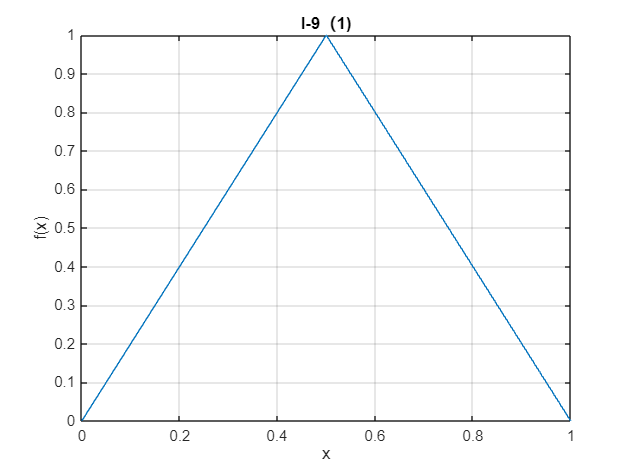

x = linspace(0, 1, 1000); 
y = zeros(size(x));  
for i = 1:length(x)  
    if x(i) < 1/2
        y(i) = 2*x(i);   
    else  
        y(i) = 2*(1-x(i));  
    end  
end   
plot(x, y);  
title('function(1)');  
xlabel('x');  
ylabel('f(x)');  
grid on;
title('I-9（1)');

(2)

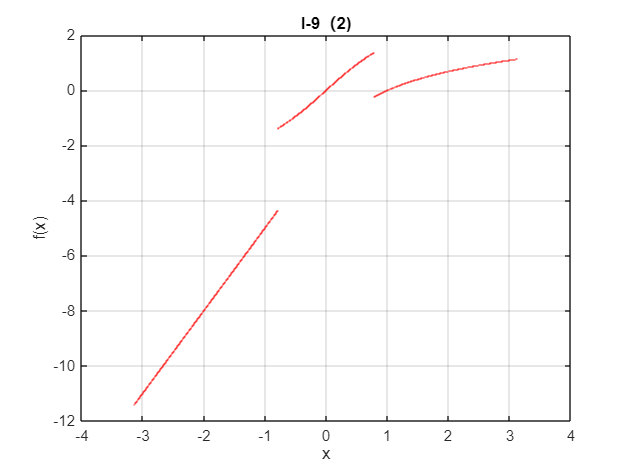

x = linspace(-pi,pi,1000000); 
y = zeros(size(x));  
for i = 1:length(x)  
    if x(i) <= -pi/4
        y(i) = 3*x(i) - 2;   
    elseif x(i) > -pi/4&&x(i) < pi/4
        y(i) = atan(x(i))+sin(x(i));  
    else
        y(i) = log(x(i));
    end
end   
plot(x, y,'ro','MarkerSize',0.3);  
title('function(2)');  
xlabel('x');  
ylabel('f(x)');  
grid on;
title('I-9（2)');

10.

(1)

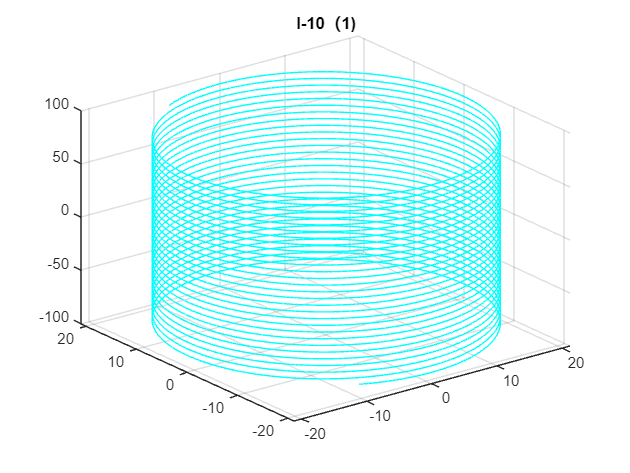

t = -90:0.001:90;
plot3((m/20)*cos(t),(m/20)*sin(t),t,'-c','MarkerSize',0.1);
grid on;
title('I-10（1)');

(2)

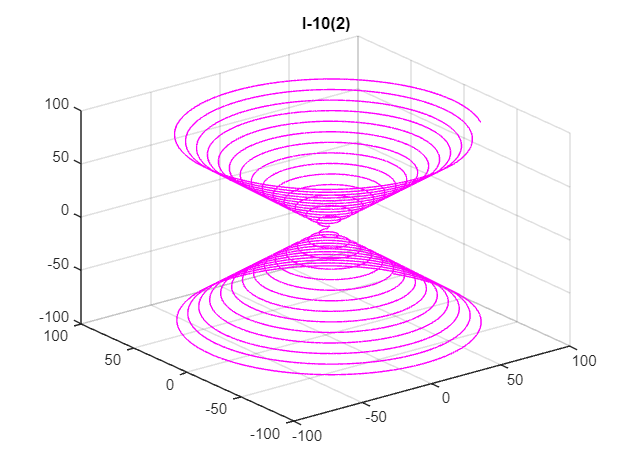

t = -90:0.001:90;
plot3(cos(t)+t.*sin(t),sin(t)-t.*cos(t),-t,'-m','MarkerSize',0.1);
grid on;
title('I-10(2)');

11.

初始化：

syms u s;
U = [0 -1 1;1 2 4];
Style = ["r--","go","m*"];
f1 = @(x,u,s)(1/(sqrt(sym(2*pi))*s)) * exp(-(x - u).^2/(2*s^2));
f2 = @(x,u,s)(sin(x)/(sqrt(sym(2*pi)).*s)) .* exp(-(x - u).^2/(2.*s^2));

(1)

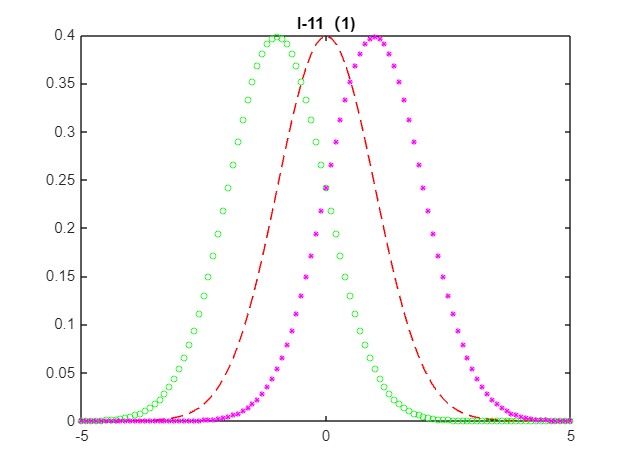

figure(1);
x = -5:0.1:5;
Y = ones([3,length(x)]);
for i=1:3
    Y(i,:) = f1(x,U(1,i),1);
end
for i=1:3
    plot(x,Y(i,:),Style(i),MarkerSize=4);
    hold on;
end
title('I-11（1)');
hold off;

(2)

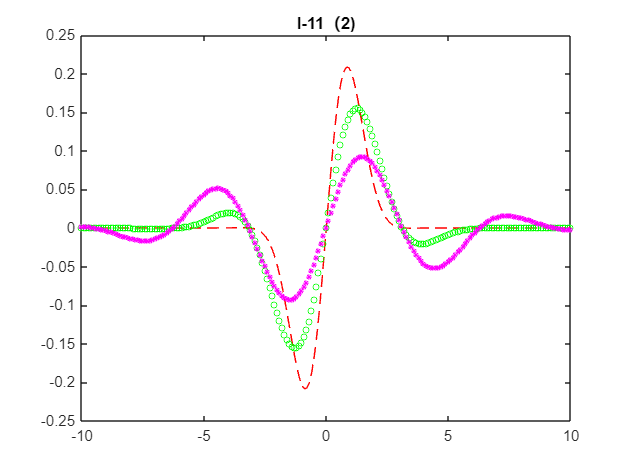

figure(1);
x = -10:0.1:10;
Y = ones([3,length(x)]);
for i=1:3
    Y(i,:) = f2(x,0,U(2,i));
end
for i=1:3
    plot(x,Y(i,:),Style(i),MarkerSize=4);
    hold on;
end
title('I-11（2)');
hold off;

12.

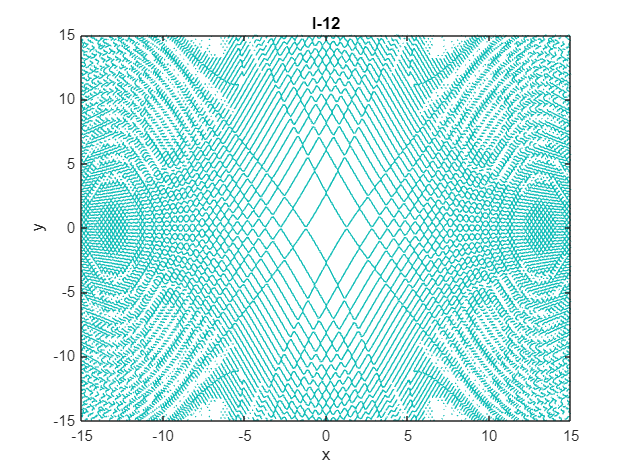

h = @(x,y) sin(x.^2 + m/2000*y.^2) - cos(x.*y);
figure(1);
ezplot(h,[-15,15,-15,15]);
title('I-12');

13.

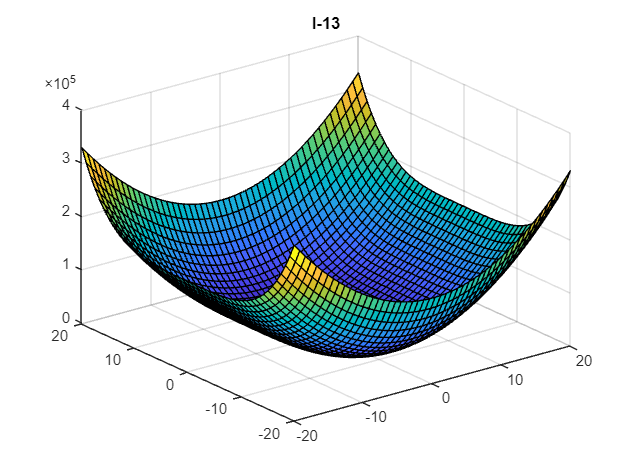

x = linspace(-20,20,50);
y = linspace(-20,20,50);
figure(1);
[X,Y] = meshgrid(x,y);
Z = m*X.^2 + Y.^4;
surf(X,Y,Z);
title('I-13');

14.

函数y = x - xsin(3x)绕x轴旋转得到的函数

即将y = sqrt(y^2 + z^2)代入原式即可，

如下，为：

整理为可赋值形式，得：

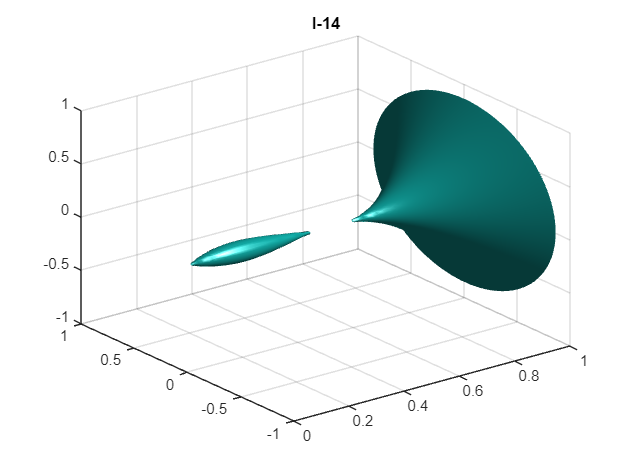

[X, Y, Z] = meshgrid(linspace(0, 1, 100),linspace(-1, 1, 100),linspace(-1, 1, 100));
F = (X - X.*sin(3.*X)).^2 - Z.^2 - Y.^2;
figure;
isosurface(X,Y,Z,F,0);
title('I-14');
grid on;

###########################

#######    SECTION 2   #######

###########################

1.

初始化：

min_x = 10000;
delta = 0.1;
% x_1 = -3;
% x_2 = -3;
% x_3 = -3;
fun = @(x)(x*1.00000)^4 - 2^x;

1)

绝对值普通遍历：

flag = 0;
for x = -2:delta:2
    if fun(x) * fun(x + delta) <= 0
        if flag == 0
            flag = 1;
            if abs(fun(x)) < abs(fun(x + delta))
                x1 = x;
            else
                x1 = x + delta;
            end
        else
            if abs(fun(x)) < abs(fun(x + delta))
                x2 = x;
            else
                x2 = x + delta;
            end
        end
    end
end
disp([x1,x2]);

   -0.9000    1.2000



2)

精度聚焦遍历：

x1 = -2;
x2 = -2;
fun_ = @(x) abs(x^4 - 2^x);
microdelta = delta/100000;
flag = 0;
X = ones([1,2]);
x_1 = -2;
x_2 = x_1 + delta;
x_3 = x_2 + delta;
for x_1 = -2:delta:2-2*delta
    x_2 = x_1 + delta;
    x_3 = x_2 + delta;
    if fun_(x_2)<fun_(x_1)&&fun_(x_2)<fun_(x_3)&&flag<=1        
        if flag==0
            min1 = fun_(x_2);
            for j = x_1:microdelta:x_3
                if fun_(j) <= min1
                    min1 = fun_(j);
                    x1 = j;
                end
            end
        else
            min2 = fun_(x_2);
            for j = x_1:microdelta:x_3
                if fun_(j) <= min2
                    min2 = fun_(j);
                    x2 = j;
                end
            end
        end
        flag = flag + 1;
    end
    
end
disp([x1,x2]);

   -0.8613    1.2396



3)

使用matlab的函数：

disp(fminbnd(fun_, -2, 0));

   -0.8613



disp(fminbnd(fun_, 0, 2));

    1.2396



2.

首先在合适的区域内画出图像：

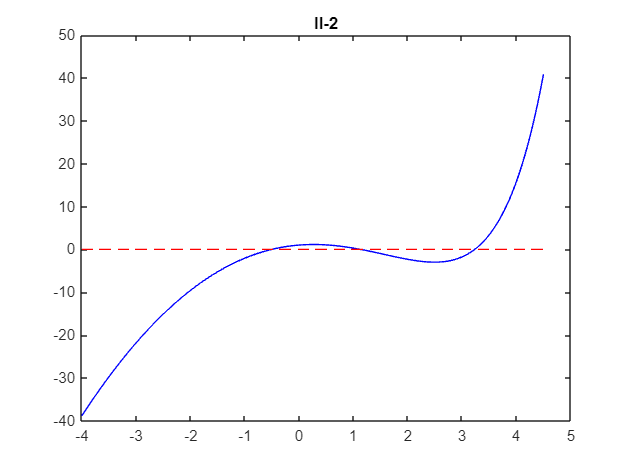

figure(1);
x_domain = -4:0.01:4.5;
y2 = zeros([1,length(x_domain)]);
fun2 = @(x)exp(x) - 3 .* m .* x.^2./(m + 100);
plot(x_domain,fun2(x_domain),'b-',x_domain,y2,'--r');
title('II-2');

如图II-2，结合函数性质，可以判断在x<-1以及x>4时图像分别趋近于-Inf和Inf，则可知根落于

（-1，4）之间。同时，由红色辅助线可以观察到函数共有三个根。

我们在此猜测，函数的三个根分别为-0.5，1，3.2

猜测根值配合matlab中的fzero函数可求得精确根如下：

XA = [-0.5 1 3.2];
RO = [-0.5 1 3.2];
for i = 1:3
    RO(i) = fzero(fun2, XA(i));
    disp(['Root',num2str(i),': ', num2str(RO(i))]);
end

Root1: -0.49989
Root2: 1.1283
Root3: 3.2348


3.

首先在合适的区域内画出图像：

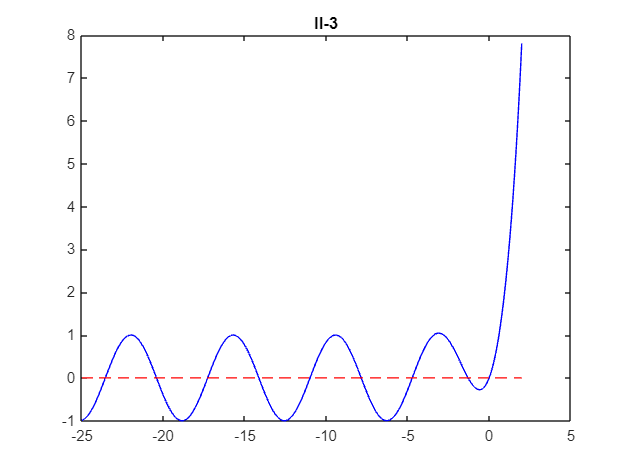

figure(1);
x_domain = -25:0.01:2;
y2 = zeros([1,length(x_domain)]);
fun3 = @(x)exp(x) - cos(x);
plot(x_domain,fun3(x_domain),'b-',x_domain,y2,'--r');
title('II-3');

如图II-3，结合函数性质，可得近似根为0，-pi/2以及-pi/2-k*pi(k>0).

在这里取前12个根，由近似值计算出精确值，有：

XA = [0 -pi/2:-pi:-pi/2-10*pi];
RO = [0 -pi/2:-pi:-pi/2-100*pi];
for i = 1:length(XA)
    RO(i) = fzero(fun3, XA(i));
    disp(['Root',num2str(i),': ', num2str(RO(i))]);
end

Root1: 0
Root2: -1.2927
Root3: -4.7213
Root4: -7.8536
Root5: -10.9956
Root6: -14.1372
Root7: -17.2788
Root8: -20.4204
Root9: -23.5619
Root10: -26.7035
Root11: -29.8451
Root12: -32.9867


对于相邻两根的差，当n->Inf 时可得：

for i = 1:length(XA)-1
    disp(['DeltaRoot',num2str(i),': ', num2str(abs((RO(i+1)-RO(i))))]);
end

DeltaRoot1: 1.2927
DeltaRoot2: 3.4286
DeltaRoot3: 3.1323
DeltaRoot4: 3.142
DeltaRoot5: 3.1416
DeltaRoot6: 3.1416
DeltaRoot7: 3.1416
DeltaRoot8: 3.1416
DeltaRoot9: 3.1416
DeltaRoot10: 3.1416
DeltaRoot11: 3.1416


由此可知，当

时，有上式等于pi。

4.

首先在合适的区域内画出图像：

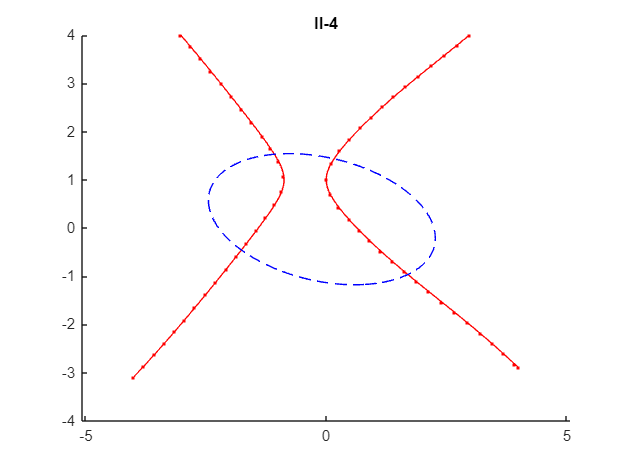

fun4_1 = @(x, y) x.^2 -y.^2 + sin(x) + 2*y - 1; 
fun4_2 = @(x, y) x.^2 +3*y.^2 + x.*y - y - 5; 
figure;
hold on;
fimplicit(fun4_1, [-4 4 -4 4], '.-r');
fimplicit(fun4_2, [-4 4 -4 4], 'b--');
axis equal;
title('II-4');
hold off;

由图像知，共有4个根，取近似根如下GP，再使用fsolve对精确根进行求解。

F = @(vars) [fun4_1(vars(1), vars(2)); fun4_2(vars(1), vars(2))];
GP = [-2 -1 0.5 1.5;-0.5 1.5 1.5 -1];
for i=1:4
    [solution, fval, exitflag] = fsolve(F, GP(:,i));
    disp(solution);
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


   -1.7626
   -0.4578




Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


   -1.0774
    1.5293




Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


    0.1630
    1.4346




Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


    1.6948
   -0.9659



5.

首先在合适的区域内画出图像：

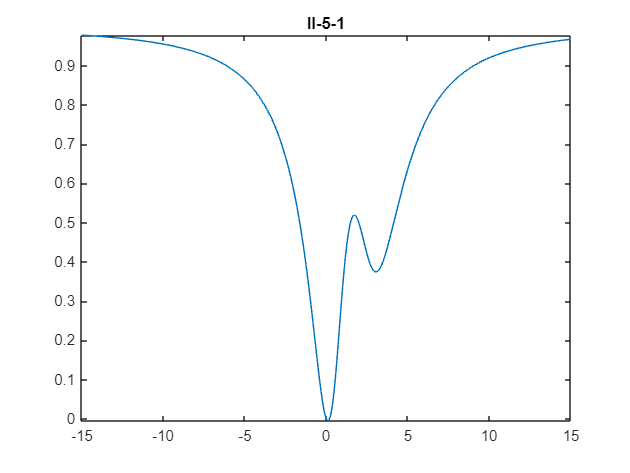

figure(1);
x_domain = -15:0.01:15;
syms x;
%y2 = zeros([1,length(x_domain)]);
fun5 = (x^2)/((x-1)^2 + x + 1) - x/((x - 3)^2 + x + 1);
fplot(fun5,[-15,15]);
title('II-5-1');
hold off;

对上述函数求导得

dfun5 = diff(fun5,x);
disp(dfun5);

$$\frac{2\,x}{x+{\left(x-1\right)}^{2}+1}-\frac{1}{x+{\left(x-3\right)}^{2}+1}+\frac{x\,\left(2\,x-5\right)}{{\left(x+{\left(x-3\right)}^{2}+1\right)}^{2}}-\frac{x^{2}\,\left(2\,x-1\right)}{{\left(x+{\left(x-1\right)}^{2}+1\right)}^{2}}$$

此时绘制出导函数图像：

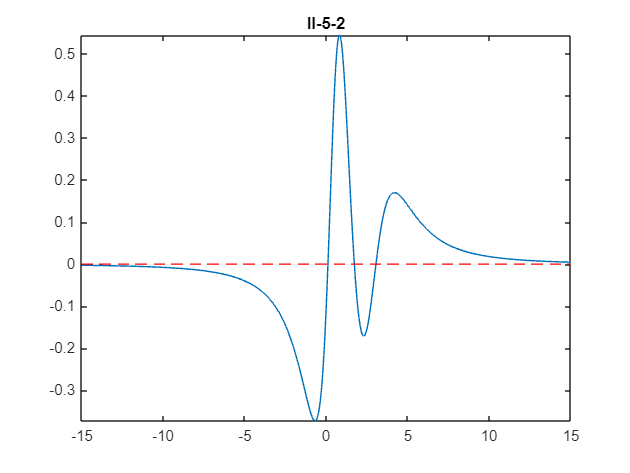

figure(1);
fplot(dfun5,[-15,15]);
hold on;
fplot(0,[-15,15],'--r');
title('II-5-2');
hold off;

如图II-5-2，结合函数性质，可以知根落于（0，5）之间。

同时，由红色辅助线可以观察到函数共有三个根。

我们在此猜测，函数的三个根分别为0.5,2,3

猜测根值配合matlab中的fzero函数可求得精确根如下：

XA = [0.5,2,3];
RO = [0.5,2,3];
for i = 1:3
    RO(i) = fzero(matlabFunction(dfun5), XA(i));
    disp(['Root',num2str(i),': ', num2str(RO(i))]);
end

Root1: 0.10347
Root2: 1.7255
Root3: 3.0498


综上，

x = `0.10347时有极小值，`

x = `1.7255时有极大值，`

x = `3.0498时有极小值，`

`单调增区间：[0.10347, 1.7255] 和 [3.0498, Inf]，`

`单调减区间：[-Inf, 0.10347] 和 [1.7255,3.0498]。`

6.

设绳长为l，半径为R，由题意可以列出：

syms l;
R = 10;
eqn = 2*acos(l/(2*R))/(2*pi)*l^2*pi - (1/2)*R^2*pi == 0;
sol = vpasolve(eqn,l,R); 
disp(sol);

$$14.142135623730950488016887242097$$

这里取R = 10，则如上接触的即为绳长。

7.

由题意可知棒最大长与斜率关系为：

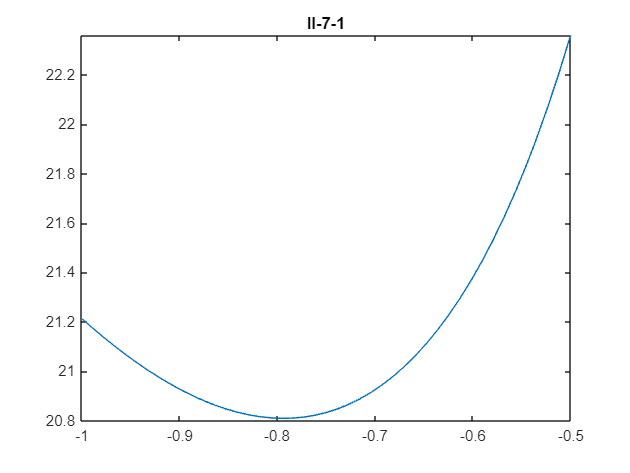

syms k;
fun7 = sqrt((5 - 10 * k)^2 + (10 - 5/k)^2);  % k < 0
fplot(fun7,[-1,-0.5]);
title('II-7-1');
hold off;

求出最小值所在点为：

minp = fminbnd(matlabFunction(fun7), -1, -0.5);
disp(minp);

   -0.7937



disp(vpa(subs(fun7,k,minp),6));

$$20.8097$$

故最短棒长为$20.8097$

8.

(1)

由题意得：

syms a b x;
L = b/sin(x) + a/cos(x);

定义域为

(2)

不妨假设

绘制函数得：

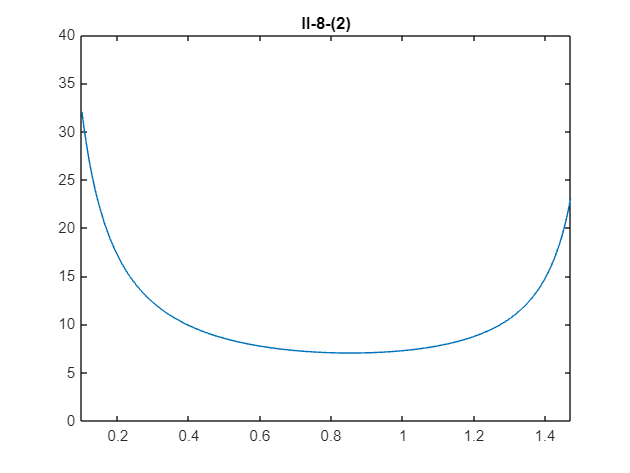

fplot(subs(subs(L,b,3),a,2),[0,pi]); 
title('II-8-(2)');
xlim([0.1,pi/2-0.1]);  % 注意：在此没有取到定义域端点，否则无法观察到函数趋势。
ylim([0,40]);

(3)

由极值的定义，类似于我在II-1-（2）中采用的方法，

我们在matlab中可以将其刻画为遍历点的函数值小于其左右两侧的函数值，如下：

minangle_ = -100;
min3 = -100;
delta = 0.01;        %如需提高精度，可将delta值调小，但运算时间会比较长
x_1 = 0.2;
x_2 = x_1 + delta;
x_3 = x_2 + delta;
for x_1 = 0.2:delta:pi/2-2*delta
    x_2 = x_1 + delta;
    x_3 = x_2 + delta;
    if subs(subs(subs(L,a,2),x,x_2),b,3)<=subs(subs(subs(L,a,2),x,x_1),b,3)&&subs(subs(subs(L,a,2),x,x_2),b,3)<=subs(subs(subs(L,a,2),x,x_3),b,3)        
        min3 = subs(subs(subs(L,a,2),x,x_2),b,3);
        minangle_ = x_2;
    end 
end
disp(minangle_);

    0.8500



disp(vpa(min3,6));

$$7.02356$$

(4)

先对函数求导：

dL = diff(subs(subs(L,b,3),a,2),x);
disp(dL);

$$\frac{2\,\sin\left(x\right)}{{\cos\left(x\right)}^{2}}-\frac{3\,\cos\left(x\right)}{{\sin\left(x\right)}^{2}}$$

令导数为零即可求出驻点。再由II-8-(2)，我们猜测驻点所在位置为0.8，以此来作为初始值进行使用：

eqn11 = dL == 0;
vpasolve(eqn11,x,0.8)

$$ans = 0.85277087756427083204247764696116$$

令人兴奋的，我们得到了比（3）中更加精确的答案，这同时证明了我们的计算的合理性。

最短的长度同理代入即可。

(5)

由II-8-(2)，我们猜测最小值在[0.6,1.2]区间内取到，将其代入fminbnd函数即可求得最终解如下：

minangle = fminbnd(matlabFunction(subs(subs(L,b,3),a,2)),0.6,1.2);
disp(minangle);

    0.8528



故当角度为0.8528（rad）时，有最短长度如下：

disp(vpa(subs(subs(subs(L,a,2),x,minangle),b,3),6));

$$7.02348$$

(6)

该题的题干描述的目的似乎不是很准确，

不过我还是按照它所说的重复做一下。

我们暂时默认使用（5）中的算法。

首先，任意改变a和b的值：

绘制函数得：

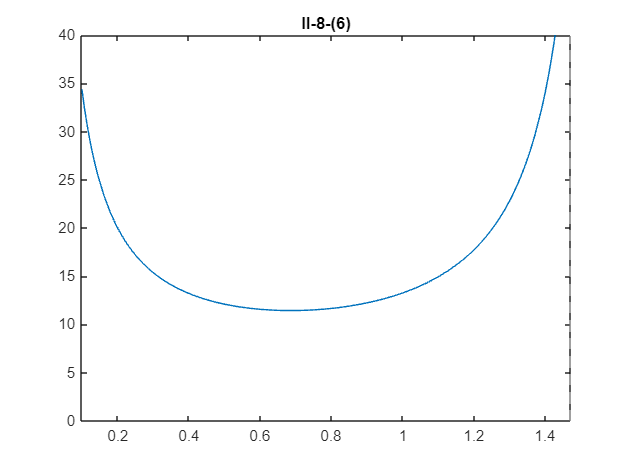

fplot(subs(subs(L,b,2.9),a,5.3),[0,pi]); 
title('II-8-(6)');
xlim([0.1,pi/2-0.1]);  % 注意：在此没有取到定义域端点，否则无法观察到函数趋势。
ylim([0,40]);

由II-8-(6)，我们猜测最小值在[0.6,0.8]区间内取到，将其代入fminbnd函数即可求得最终解如下：

minangle = fminbnd(matlabFunction(subs(subs(L,b,2.9),a,5.3)),0.6,0.8);
disp(minangle);

    0.6856



故当角度为`0.6856`（rad）时，有最短长度如下：

disp(vpa(subs(subs(subs(L,a,5.3),x,minangle),b,2.9),6));

$$11.4276$$

(7)

由原式整理得：

syms x_ a_ L_;
b_ = sin(x_)*(L_ - a_/cos(x_));

绘制图像：

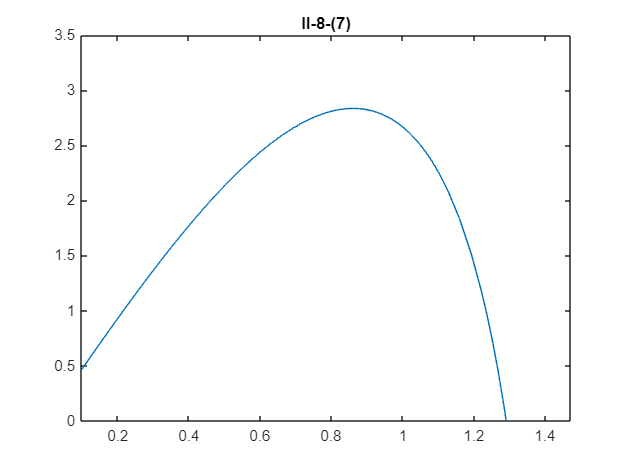

fplot(subs(subs(b_,L_,6.5),a_,1.8),[0,pi/2]); 
title('II-8-(7)');
xlim([0.1,pi/2-0.1]);  % 注意：在此没有取到定义域端点，否则无法观察到函数趋势。
ylim([0,3.5]);
hold off;

由II-8-(2)，我们猜测最大值在[0.6,1]区间内取到，将其代入fminbnd函数即可求得最终解如下：

maxangle = fminbnd(matlabFunction(10 - subs(subs(b_,L_,6.5),a_,1.8)),0.6,1); %这里用一个常数减去函数得到有极小值的函数以方便计算。
disp(maxangle);

    0.8608



故当角度为`0.8608`（rad）时，有最大高度如下：

disp(vpa(subs(subs(subs(b_,L_,6.5),a_,1.8),x_,maxangle),7));

$$2.835181$$

###########################

#######    SECTION 3   #######

###########################

1.

首先判断函数的根的情况：

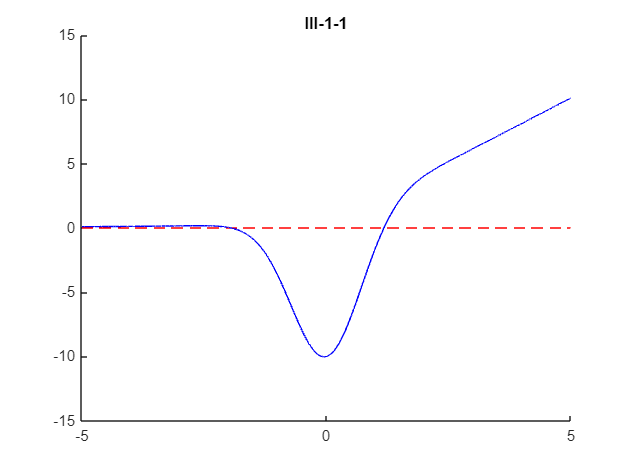

cla reset;
m = 424;
fun_1 = @(x)(x + sqrt(x.^2 + 1) - 11*exp(-x.^2));
x = -5:0.001:5;
hold on;
fplot(0,[-5,5],'--r');
plot(x,fun_1(x),'-b');
hold off;
title('III-1-1');

%legend();

由图III-1-1可知其根落于[-5,0]与[0,5]两个区域内。

初始化定义域、迭代次数：

l1 = -5;r1 = 0;
l2 = 0 ;r2 = 5;
iter1 = 0;
iter2 = 0;
clear logger1;
clear logger2;
logger1(1) = 0;
logger2(1) = 0;

分别对这两个区域内的根做二分法与黄金分割法的逼近：

1）二分法：

% 根1
while ~((fun_1(l1)-0<1e-9)||(0-fun_1(r1)<1e-9))
    iter1 = iter1 + 1;
    if (fun_1((l1+r1)/2)) > 0
        l1 = (l1 + r1)/2;
        logger1(iter1) = l1;
    else 
        r1 = (l1 + r1)/2;
        logger1(iter1) = r1;
    end
end
% 根2
while ~((fun_1(r2)-0<1e-9)||(0-fun_1(l2)<1e-9))
    iter2 = iter2 + 1;
    if (fun_1((l2+r2)/2)) < 0
        l2 = (l2 + r2)/2;
        logger2(iter2) = l2;
    else 
        r2 = (l2 + r2)/2;
        logger2(iter2) = r2;
    end
end

2）0.618法

初始化：

l1 = -5;r1 = 0;
l2 = 0 ;r2 = 5;
iter3 = 0;
iter4 = 0;
clear logger3;
clear logger4;
logger3(1) = 0;
logger4(1) = 0;
phi = vpa((sqrt(5)-1)/2,10);

计算：

% 根1
while ~((fun_1(l1)-0<1e-9)||(0-fun_1(r1)<1e-9))
    iter3 = iter3 + 1;
    if fun_1(l1+(r1-l1)*phi) > 0
        l1 = l1+(r1-l1)*phi;
        logger3(iter3) = l1;
    else 
        r1 = l1+(r1-l1)*phi;
        logger3(iter3) = r1;
    end
end
% 根2
while ~((fun_1(r2)-0<1e-9)||(0-fun_1(l2)<1e-9))
    iter4 = iter4 + 1;
    if fun_1(r2-(r2-l2)*phi) < 0
        l2 = r2-(r2-l2)*phi;
        logger4(iter4) = l2;
    else 
        r2 = r2-(r2-l2)*phi;
        logger4(iter4) = r2;
    end
end

3)性能对比：

a）根1：

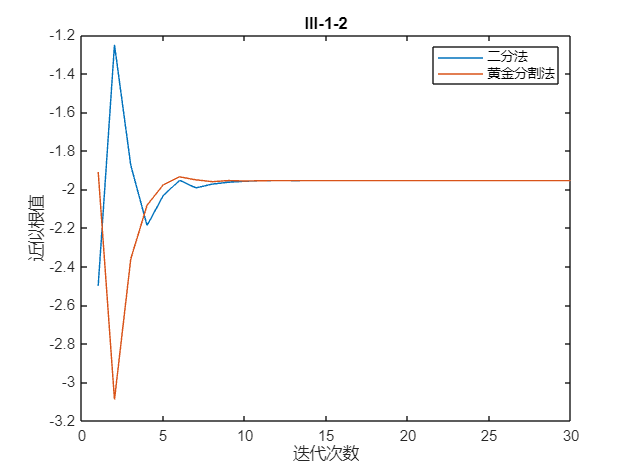

figure(1);
xd = 1:1:length(logger3);
plot(xd,logger1,xd,logger3);
legend('二分法','黄金分割法');
title('III-1-2');
xlabel('迭代次数');
ylabel('近似根值');
hold off;

迭代次数比较：

disp(['二分法迭代次数：',num2str(iter1)]);disp(['黄金分割法迭代次数：',num2str(iter3)]);

二分法迭代次数：30
黄金分割法迭代次数：30


b）根2：

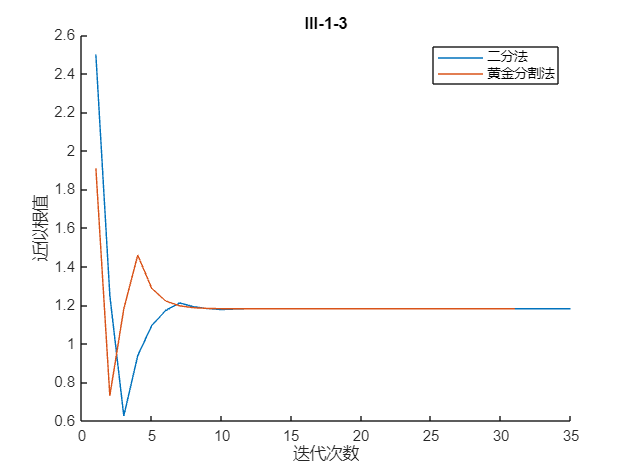

cla reset;
figure(1);
xd1 = 1:1:length(logger2);
xd2 = 1:1:length(logger4);
hold on;
plot(xd1,logger2);
plot(xd2,logger4);
legend('二分法','黄金分割法');
title('III-1-3');
xlabel('迭代次数');
ylabel('近似根值');
hold off;

迭代次数比较：

disp(['二分法迭代次数：',num2str(iter2)]);disp(['黄金分割法迭代次数：',num2str(iter4)]);

二分法迭代次数：35
黄金分割法迭代次数：31


综上，`黄金分割法在迭代过程中效果较好。`

2.

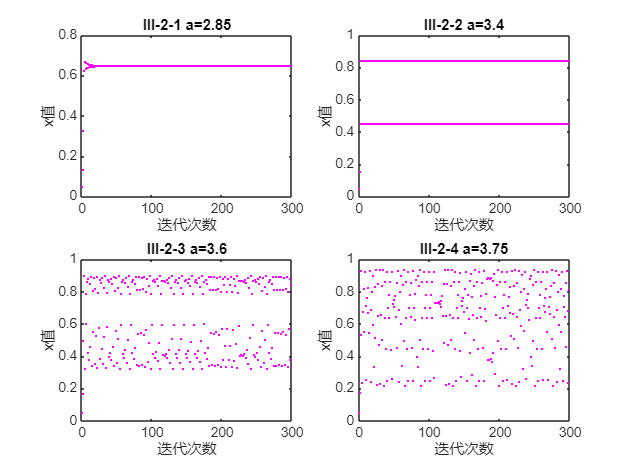

x0 = 1/sqrt(m);
num_iterations = 300;
a_list = [2.85, 3.4, 3.6, 3.75];
figure;
for i = 1:length(a_list)
    a = a_list(i);
    xn = zeros(num_iterations, 1);
    xn(1) = x0;
    for j = 2:num_iterations
        xn(j) = a * xn(j-1) * (1 - xn(j-1));
    end
    subplot(2, 2, i);
    plot(1:num_iterations, xn, 'mo','MarkerSize',1);
    title(['III-2-',num2str(i),' a=', num2str(a)]);
    xlabel('迭代次数');
    ylabel('x值');
end
hold off;

分析：

图III-2-1反映的迭代过程具有收敛性，无周期性，不具有混沌特征。

图III-2-2反映的迭代过程不具有收敛性，无周期性，不具有混沌特征

图III-2-3反映的迭代过程不具有收敛性，具有无规律的周期轨道，具有较为明显的混沌特征。

图III-2-4反映的迭代过程不具有收敛性，具有无规律的周期轨道，具有较为明显的混沌特征。

3.

设总人口为p：

syms p;

状态转移矩阵为：

tranmat = [0.95 0.01;0.05 0.99];

初始状态设为乡村城市人口比例为：

status = [0.8;0.2];s

$$s = s$$

(1)

一年以后的迭代结果：

disp(vpa(tranmat * status * p,3));

$$\left(\begin{array}{c} 0.762\,p\\ 0.238\,p \end{array}\right)$$

两年以后的迭代结果：

disp(vpa(tranmat^2 * status * p,3));

$$\left(\begin{array}{c} 0.726\,p\\ 0.274\,p \end{array}\right)$$

十年以后的迭代结果：

disp(vpa(tranmat^10 * status * p,3));

$$\left(\begin{array}{c} 0.508\,p\\ 0.492\,p \end{array}\right)$$

（2）

设迭代次数为n:

syms  n;

n年以后的迭代结果：

disp(vpa(tranmat^n * status * p,2));

$$\left(\begin{array}{c} p\,\left(0.63\,{\mathrm{e}}^{-0.062\,n}+0.17\right)\\ -1.0\,p\,\left(0.63\,{\mathrm{e}}^{-0.062\,n}-0.83\right) \end{array}\right)$$

这里虽然计算出了答案，但是事实上在计算矩阵的幂时还可以通过正交变换来进行计算。

这样使得计算更加简单，因为在某些情况下，matlab无法完成对于一个带参数的矩阵的幂运算。

方法如下：

[S,D] = eig(tranmat);
disp(vpa(S*(D^n)/S*status*p,2))

$$\left(\begin{array}{c} p\,\left(0.63\,0.94^{n}+0.17\right)\\ -p\,\left(0.63\,0.94^{n}-0.83\right) \end{array}\right)$$

这里我们会惊奇的发现两者的结果居然表达不一样，

因为一个e为底的指数绝对不会等于一个有理数为底的指数！

但是我们的算法表达式没有错，如下我们将n = 20代入两式中分别观察结果：

disp(subs(vpa(tranmat^n * status * p,2),n,20));

$$\left(\begin{array}{c} 0.35040061914187267249829121239843\,p\\ 0.64959938088723115795844249121485\,p \end{array}\right)$$

disp(subs(vpa(S * (D^n)/S * status * p,2),n,20));

$$\left(\begin{array}{c} 0.35040061914610637649054533459279\,p\\ 0.64959938076658213213925355456737\,p \end{array}\right)$$

这时，我们又一次惊奇的发现，两种算法在小数点后前10位完全相同，而10位之后出现了差异。

因此，我们可以猜测，第二种算法某种意义上由于使用了具体数目的幂运算（即特征对角阵D

的幂运算），在计算过程中必然会有相关的损失，但是这个损失是几乎微乎其微的，因此我们

几乎在小数点后10位才能够观察到这一现象。

总结来说，第一种算法中matlab采用的是一种解析算法，而第二种则是一种数值算法。

（3）

 初始状态设为乡村城市人口比例为：

status2 = [0.7;0.3];

n年以后的迭代结果：

disp(vpa(tranmat^n * status2 * p,2));

$$\left(\begin{array}{c} p\,\left(0.53\,{\mathrm{e}}^{-0.062\,n}+0.17\right)\\ -1.0\,p\,\left(0.53\,{\mathrm{e}}^{-0.062\,n}-0.83\right) \end{array}\right)$$

（4）

由（2）（3），我们计算出n趋于Inf时城市乡村占比的极限：

disp(vpa(limit(tranmat^n * status * p,n,Inf),2));

$$\left(\begin{array}{c} 0.17\,p\\ 0.83\,p \end{array}\right)$$

disp(vpa(limit(tranmat^n * status2 * p,n,Inf),2));

$$\left(\begin{array}{c} 0.17\,p\\ 0.83\,p \end{array}\right)$$

发现n趋于Inf时，城乡比例都收敛与同一值，说明这与城乡初始比值是无关的。

那么最后的收敛值与什么有关呢？

题中让我们寻找它与状态转移矩阵的最大特征值对应特征向量的关系，而最大特征值又与城乡转出比例有关，

于是我们在此重新定义我们的状态转移矩阵：

syms c t;
tranmat_ = [(1-t) c;t (1-c)];

这时，将它特征化，会得到解析解吗？

[Q,W] = eig(tranmat_)

$$Q = \left(\begin{array}{cc} \frac{c}{t} & -1\\ 1 & 1 \end{array}\right)$$

$$W = \left(\begin{array}{cc} 1 & 0\\ 0 & 1-t-c \end{array}\right)$$

答案是可以的，这时我们发现，W中显示的两个特征值中1永远是大于1-t-c的，故其对应的特征向量

Q(:,1)

$$ans = \left(\begin{array}{c} \frac{c}{t}\\ 1 \end{array}\right)$$

与最终的城乡比例收敛值有关。

换句话说，就是城乡比例收敛值与城乡转出的比例有关，而这满足什么样的关系呢？

不妨先令农村转出率为0.1，设k为城市转出率与农村转出率的比值，其作为自变量，而最终的城市人口比例设置因变量

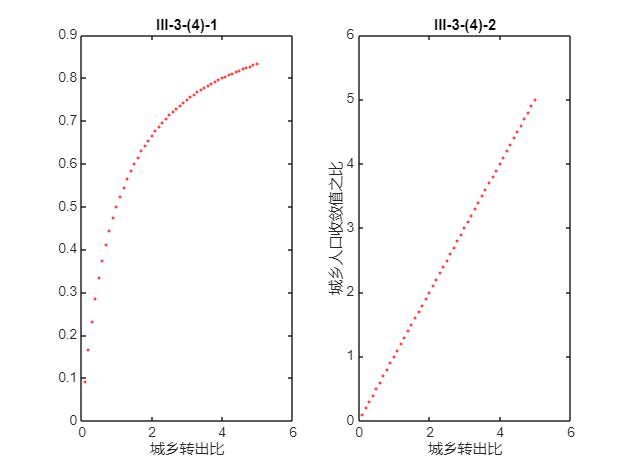

t = 0.1;
clear y y2;
y(1) = 0;
y2(1) = 0;
y_ = ones([2,1]);
%%由于即将做矩阵运算，而自变量本身就是矩阵，故只能用for循环来完成计算
m = 0;
for k = 0.1:0.1:5    %此处区间两端互为倒数
    m = m + 1;
    tranmat2 = [(1-t) k*t;t (1-k*t)];
    y_ = vpa(limit(tranmat2^n * status,n,Inf),2);
    y(m) = y_(1);%/y_(2);
    y2(m) = y_(1)/y_(2);
    %[Q2,W2] = eig(tranmat2);
end
close all;
cla reset;
k = 0.1:0.1:5;
subplot(1,2,1);
plot(k,y,'ro',MarkerSize=1.3);
title('III-3-(4)-1');
xlabel('城乡转出比');
subplot(1,2,2);
plot(k,y2,'ro',MarkerSize=1.3);
title('III-3-(4)-2');
xlabel('城乡转出比');
ylabel('城乡人口收敛值之比');

由此可知

城乡转出比等于城乡人口收敛值之比。

4.

由题意，递推公式可由下矩阵形式给出：

于是可以根据此求解：

Mat = sym([1 1; 1 0]);
[Q3, W3] = eig(Mat);
x0 = [2; 1]; % INITIALIZATION
syms n; 
result = simplify(Q3 * W3^n / Q3 * x0);

n此迭代后的矩阵：

disp(result);

$$\begin{array}{l} \left(\begin{array}{c} \frac{2\,\sqrt{5}\,\sigma_{2}}{5}-\frac{2\,\sqrt{5}\,\sigma_{1}}{5}+\sigma_{1}+\sigma_{2}\\ \frac{3\,\sqrt{5}\,\sigma_{2}}{10}-\frac{3\,\sqrt{5}\,\sigma_{1}}{10}+\frac{\sigma_{1}}{2}+\frac{\sigma_{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{n}\\ \sigma_{2}={\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{n} \end{array}$$

通项公式

disp(result(1));

$$\frac{2\,\sqrt{5}\,{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{n}}{5}-\frac{2\,\sqrt{5}\,{\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{n}}{5}+{\left(\frac{1}{2}-\frac{\sqrt{5}}{2}\right)}^{n}+{\left(\frac{\sqrt{5}}{2}+\frac{1}{2}\right)}^{n}$$

5.(综合实验）

设胜负矩阵如下：

MM = [0 1 0 1 1 1;
      0 0 0 1 1 1;
      1 1 0 1 0 0;
      0 0 0 0 1 1;
      0 0 1 0 0 1;
      0 0 1 0 0 0;];

如果我们将总胜场数列出：

Vec = [4;
       3;
       3;
       2;
       2;
       1];
Vec = ones(6,1)

Vec =      1
     1
     1
     1
     1
     1


会发现有部分的胜场次出现了重合，这不利于我们对其进行排名，于是，我们在此将MM与Vec相乘得到一个带有权重的胜场次,再不断结果与MM相乘迭代、归一，最终得到一个收敛的得分向量。

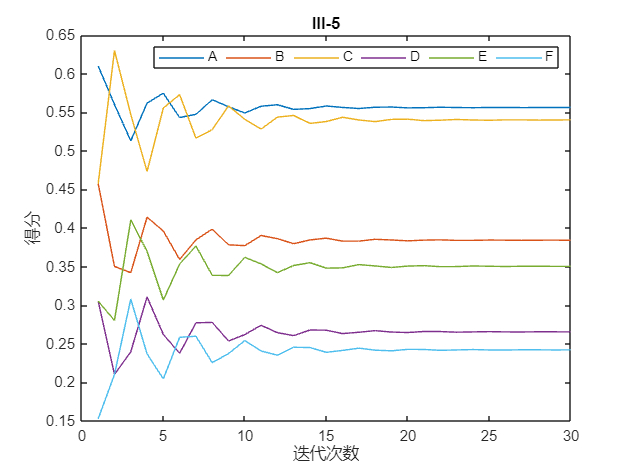

clear V;
close all;
V(:,1) = zeros(6,1);
syms n;
for i = 1:30
    Vec = MM * Vec;
    Vec = Vec/norm(Vec);
    V(:,i) = Vec;
end

for i = 1:6
    plot(V(i,:));
    hold on;
end
title('III-5');
xlabel('迭代次数');
ylabel('得分');
legend('A','B','C','D','E','F','NumColumns',6);
hold off;

个选手收敛得分如下：

disp(Vec);

    0.5561
    0.3840
    0.5401
    0.2652
    0.3502
    0.2419



故排名为

A C B E D F

###########################

#######    SECTION 4   #######

###########################

1.

(1)

记概率公式如下P：

clear S;
close all;
S(1) = 0;
warning('off');
P = @(n) nchoosek(365,n) * factorial(n) / 365^n;

计算：

for i=1:100
    S(i) = P(i);
end
warning('on');

绘图：

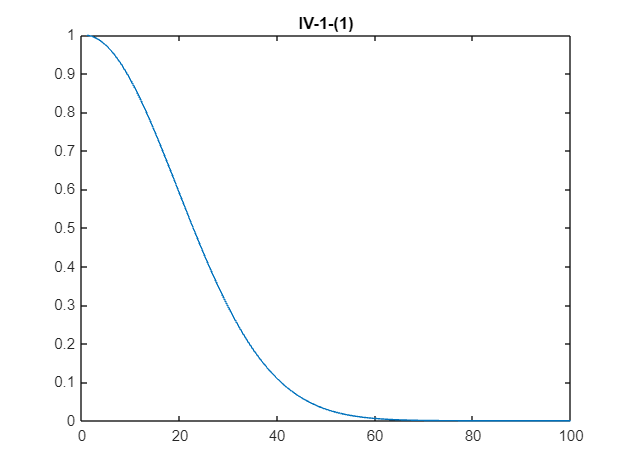

plot(S);
title('IV-1-(1)');

（2）

clear S;
S(1) = 0;
ExpS(1) = 0;
warning('off');
P = @(n) nchoosek(365,n) * factorial(n) / 365^n;
epochs_mat = [20 100 500 1200];

计算：

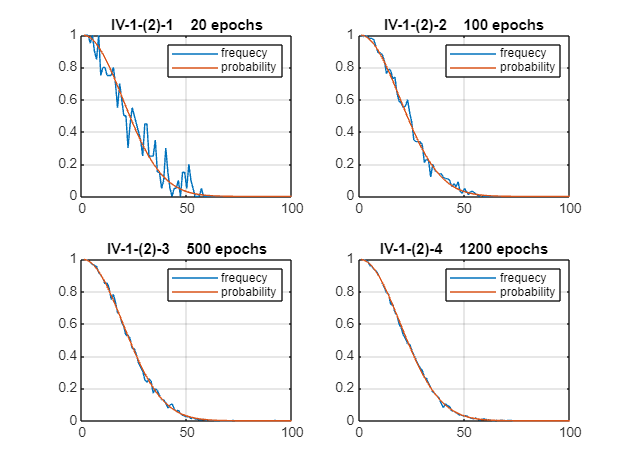

for a = 1:length(epochs_mat)
    epochs = epochs_mat(a);
    for i=1:100
        simmf = 0;
        for ext = 1:epochs        
            clear ExpS;
            for j = 1:i
                flag = 0;
                ExpS(j) = randi([1, 365]);
                if j>1
                    for k = 1:j-1
                        if ExpS(k) == ExpS(j)
                            simmf = simmf + 1;
                            flag = 1;
                            break;
                        end
                    end
                end
                if flag == 1
                    break;
                end
            end
        end
        S(i) =1 - simmf/epochs;
    end
    subplot(2,2,a);
    plot(S);
    title(['IV-1-(2)-',num2str(a),'    ',num2str(epochs_mat(a)),' epochs']);
    hold on;
    clear S;
    for i=1:100
        S(i) = P(i);
    end
    plot(S);
    legend('frequecy','probability');
    hold off;
    grid on;
end

不同的epochs对应频率概率差异可由如上图直观地看出来。

（3）

原函数为：

close all;
syms n;
P = nchoosek(365,n) * factorial(n) / 365^n;
%P = factorial(365)/((365^n) * factorial(n));

由于高阶泰勒展开精确性没有想象中那么高，我们在这里使用分段泰勒展开：

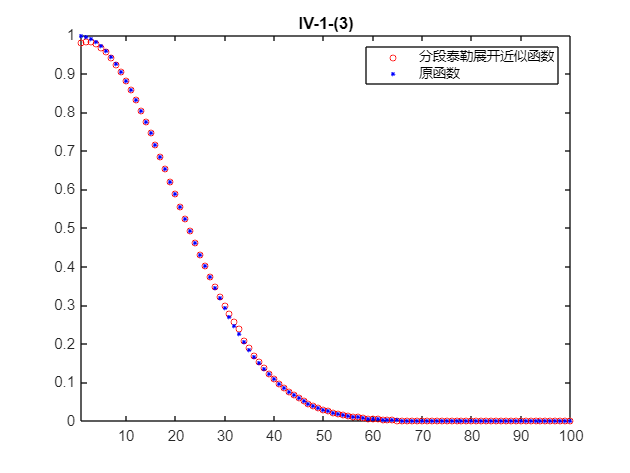

P_1 = vpa(taylor(P,n,'ExpansionPoint',33/2,'order',5),2);
P_2 = vpa(taylor(P,n,'ExpansionPoint',34+33/2,'order',5),2);
P_3 = vpa(taylor(P,n,'ExpansionPoint',66+33/2,'order',5),2);
clear PP;
warning('off');
PP(1) = 0;
%plot(1:100,P_(1:100));
for ii = 1:100
   if ii>=1&&ii<=33
       PP(ii) = subs(P_1,n,ii); 
   elseif ii>=34&&ii<=66
       PP(ii) = subs(P_2,n,ii);
   else
       PP(ii) = subs(P_3,n,ii);
   end
end
plot(PP,'ro',MarkerSize=4);
ylim([0 1]);
xlim([1 100]);
hold on;
title('IV-1-(3)');
clear S;
S(1) = 0;
for i=1:100
    S(i) = nchoosek(365,i) * factorial(i) / 365^i;
end
plot(S,'b*',MarkerSize=3);
legend('分段泰勒展开近似函数','原函数');

warning('on');

2.

定义x,y数据：

x = [0.11  0.25  0.3  0  -1.2  -0.33  -2  1  2.3];
y = [0.85 1.22 0.5  1.03  1.55  0.44  0.8  2.3  3.5];

使用 polyfit 进行 5 次多项式拟合：

degree = 5;
p = polyfit(x, y, degree);
y_ = polyval(p, x);
error_sum = sum((y - y_).^2);

拟合多项式如下：

disp(vpa(poly2sym(p),3));

$$0.0478\,x^{5}-0.23\,x^{4}-0.173\,x^{3}+1.29\,x^{2}+0.622\,x+0.708$$

拟合误差平方和如下：

disp(error_sum);

    0.4841



直观地，我们可以绘制原始数据与拟合函数的图像来查看拟合效果：

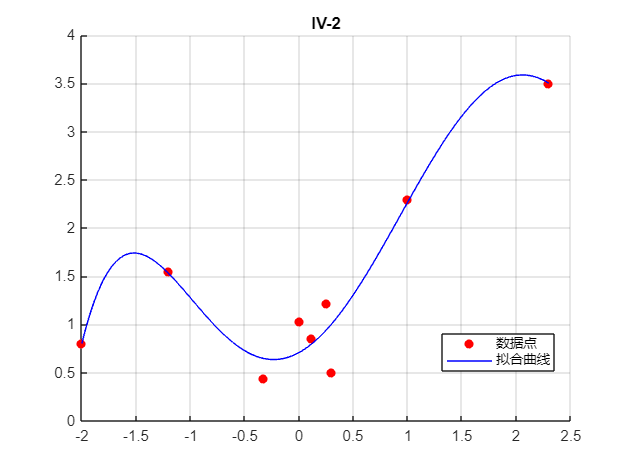

figure;
scatter(x, y, 'r', 'filled'); 
hold on;
x_ = linspace(min(x), max(x), 1000); 
y_curve = polyval(p, x_); 
plot(x_, y_curve, 'b-'); 
title('IV-2');
legend(["数据点", "拟合曲线"], "Position", [0.7035 0.2176 0.1768, 0.0774]);
hold off;
grid on;

3.

首先我们绘制草图，红色为限制区域

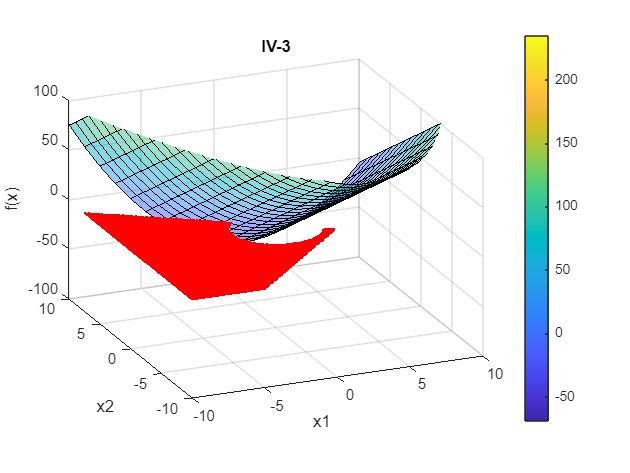

x1 = linspace(-10,10,20);
x2 = linspace(-10,10,20);
[X1,X2] = meshgrid(x1,x2);
F = X1.^2 - 4 * X1 - 8 * X2 + 15;
surf_handle = surf(X1,X2,F);
hold on;
clear x1 x2;
x1(1) = 0;
x2(1) = 0;
m = 0;
for x_1 = -10:0.1:10
    for x_2 = -10:0.1:10
        if(-(x_1)^2-(x_2)^2 <= -9)&&(2*x_1+3*x_2 <= 2)&&(x_1-x_2 <= 5)
            m = m + 1;
            x1(m) = x_1;
            x2(m) = x_2;
        end
    end
end
plot(x1,x2,'ro',MarkerSize=1);
xlim([-10 10]);
ylim([-10 10]);
daspect([1, 1, 15]);
alpha(surf_handle, 0.5);
title('IV-3');
view([-23 20]);
colorbar
ax = gca;
chart = ax.Children(1);
xlabel('x1');
ylabel('x2');
zlabel('f(x)');
zlim([-100 100]);
%surf_handle.removeAllDataCursors;
datatip(surf_handle);
delete(findall(gcf, 'Type', 'DataTip'));

由图IV-3可知，最小值在（0，0）附近，我们将（0，0）设为初始优化点。

A = [0, 0;
     2, 3;
     1, -1];
b = [-9;
      2;
      5];
x0 = [0; 5];
% 目标函数
minf = @(x) (x(1))^2 - 4*x(1) - 8*x(2) + 15;
[x, fval, exitflag, output] = fmincon(minf, x0, A, b);


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



最优解：

disp(x);

   -0.6789
    1.1068



最优目标函数值：

disp(fval);

    9.3222



4.

定义数据：

t_data = 0:24;
T_data = [15 13 13 14 14 15 16 18 20 22 23 25 28 31, 32, 31, 30, 27, 25, 24, 22, 20, 18, 17, 16];

 定义模型函数：

f_model = @(params, t) params(1) * exp(params(2) * (t - params(3)).^2);
g_model = @(params, t) params(1) * sin(pi/12 * t + params(2)) + params(3);

我们在这里粗略猜测一下初始值：

initial_guess_f = [30, -0.1, 10];
initial_guess_g = [15, 0, 15];   

利用自定义最小二乘计算：

params_f = lsqcurvefit(f_model, initial_guess_f, t_data, T_data);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


params_g = lsqcurvefit(g_model, initial_guess_g, t_data, T_data);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



% 计算拟合后的数据
T_fit_f = f_model(params_f, t_data);
T_fit_g = g_model(params_g, t_data);


损失计算：

error_f = norm(T_data - T_fit_f);
error_g = norm(T_data - T_fit_g);

优化后的模型函数为：

fprintf('f(t) = %.2f * exp(%.2f * (t - %.2f)^2)\ng(t) = %.2f * sin(pi/12*t + %.2f) + %.2f',params_f(1), params_f(2), params_f(3),params_g(1), params_g(2), params_g(3));

f(t) = 28.15 * exp(-0.01 * (t - 14.19)^2)
g(t) = 8.42 * sin(pi/12*t + -2.23) + 21.43

模型f(t)，g(t)的误差分别为：

disp(error_f);disp(error_g);

   11.7660

    4.8960



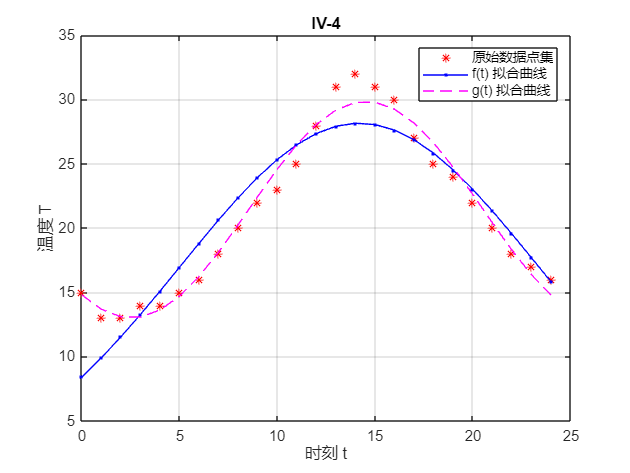

% 绘制拟合效果图
figure;
plot(t_data, T_data, 'r*', 'DisplayName', '原始数据点集');
hold on;
plot(t_data, T_fit_f, 'b.-', 'DisplayName', 'f(t) 拟合曲线');
plot(t_data, T_fit_g, 'm--', 'DisplayName', 'g(t) 拟合曲线');
xlabel('时刻 t');
ylabel('温度 T');
title('IV-4');
legend('Location', 'best');
grid on;
hold off;

5.

首先定义工作日对应矩阵：

workmat = [2, 1, 6;
           4, 5, 1;
           4, 4, 3];

根据题目要求我们设`木工的日工资数、电工的日工资数以及油漆工的日工资数分别为X、Y、Z，则三人的总支付可表示为：`

`三人的总收益可表示为`

`这时我们将两者用等号连接：`

这个表达式让我们敏感地想到了特征值与特征向量，这时我们尝试性地求解workmat的特征向量及特征值如下：

[Q3,W3] = eig(workmat)

Q3 =    -0.5412   -0.8111    0.7071
   -0.5587    0.4867   -0.7071
   -0.6285    0.3244   -0.0000


W3 =    10.0000         0         0
         0   -1.0000         0
         0         0    1.0000


此时我们发现10正好就是特征值，那么与其特征向量共线的向量（满足在60-80之间的）就是我们要求解的向量了。

故工资通解为：

syms k;
disp(Q3(:,1)*k);

$$\left(\begin{array}{c} -\frac{31\,\sqrt{3281}\,k}{3281}\\ -\frac{32\,\sqrt{3281}\,k}{3281}\\ -\frac{36\,\sqrt{3281}\,k}{3281} \end{array}\right)$$

约分后乘2得到一个合适的答案：

`木工的日工资数、电工的日工资数以及油漆工的日工资数分别为 `62 64 72 

###########################

#######    SECTION 5   #######

###########################

综合练习一

总题干：

投入产出问题 某地有三个产业，一个煤矿，一个发电厂和一条铁路，开采一元钱的煤，煤矿要 支付 0.25 元的电费及 0.35 元的运输费; 生产一元钱的电力，发电厂要支付 0.40 元的煤费，0.05 元的电费及 0.10 元的运输费; 创收一元钱的运输费,铁路要支付 0.45 元的煤费和 0.10 元的电费和 0.10 元的运输费。在某一周内煤矿接到外地金 额 50000 元定货，发电厂接到外地金额 25000 元定货，外界对地方铁路的需求 为 30000 元。

(1) 三个企业一周内的总产值多少才能满足自身及外界需求?

首先，定义直接消耗矩阵：

A = [0   , 0.40, 0.45;
     0.25, 0.05, 0.10;
     0.35, 0.10, 0.10];

定义需求量D：

D = [50000;25000;30000];

单位矩阵与A相减得到Leontief矩阵，Leontief矩阵与产出量向量X相乘即为需求量如下：

即：

X = (eye(3)-A)\D

X = 1.0e+05 *

    1.1446
    0.6540
    0.8511


(2)三个企业之间相互支付多少金额?三个企业各创造多少新价值?

相互支付金额为：

S = A * diag(X)

S = 1.0e+04 *

         0    2.6158    3.8300
    2.8615    0.3270    0.8511
    4.0060    0.6540    0.8511


三个企业各创造的新价值为：

V = X - (ones(1,3) * S)'

V = 1.0e+04 *

    4.5783
    2.9428
    2.9789


 (3)如果煤矿需要增加总产值 10000 元，它对各个企业的产品或服务的完全需求分别将是多少?

由题意，总产值发生变化，有X变为了X_：

X_(1) = X(1)+10000;
X_(2,1) = X(2,1);
X_(3,1) = X(3,1)

X_ = 1.0e+05 *

    1.2446
    0.6540
    0.8511


有新的S_：

S_ = A * diag(X_)

S_ = 1.0e+04 *

         0    2.6158    3.8300
    3.1115    0.3270    0.8511
    4.3560    0.6540    0.8511


此时的第一列反映了煤炭企业在三个企业中的产品分配。

(eye(3)-A) * X_

ans = 1.0e+04 *

    6.0000
    2.2500
    2.6500


此时的第一行反映了煤炭对社会需求量的值。

(4)假定三企业的外部需求仍是用于城镇的各种消费和积累，其中用于消费的产品价值分别为 35000 元、18000 元和 20000 元，而假定三个企业的新创造价 值又包括支付劳动报酬(工资等)和纯收入，其中支付劳动报酬分别为 25488 元、 10146 元和 14258 元，试分析各企业产品使用情况的比例关系以及该周系统的经济效益。

Ratio_mat = [S';D'];
Rsum = sum(Ratio_mat);
for i = 1:3
Ratio_mat(:,i) = Ratio_mat(:,i)/Rsum(i);
end
disp(Ratio_mat);

         0    0.4376    0.4707
    0.2285    0.0500    0.0768
    0.3346    0.1301    0.1000
    0.4368    0.3823    0.3525



该表反映了各企业产品使用情况。

（注：如上的第四行为社会需求量的比值。）

由每个企业新获得的价值减去劳动报酬得到对应每个企业的全体劳动者的剩余价值：

R = V - [25488;10146;14258]

R = 1.0e+04 *

    2.0295
    1.9282
    1.5531


总剩余价值为：

SR = sum(R)

SR = 5.5108e+04

各企业产品利润可以表示为：

W = R + [35000;18000;20000]

W = 1.0e+04 *

    5.5295
    3.7282
    3.5531


各企业总产品利润为：

SW = sum(W)

SW = 1.2811e+05

总收益T:

T = SW + SR

T = 1.8322e+05

剩余价值和产品利润反映了这三个企业的经济效益。

由总收益可得出结论:

各企业以及三者构成的经济系统效益良好。

(5)若在以后的三周内，企业外部需求的增长速度分别是 15%、3%和 12%，那么各企业的总产值将增长多少?

由题意可得企业外部需求增长速率矩阵如下:

v_g = [1.15 1.03 1.12];

迭代三轮后有：

v_g_t = v_g.^3;

将速率矩阵与需求量对应相乘得到新的需求量如下：

D_ = D .* v_g_t'

D_ = 1.0e+04 *

    7.6044
    2.7318
    4.2148


对D_做如（1）中相同的操作可以得到总产值

X_2 = (eye(3)-A)\D_

X_2 = 1.0e+05 *

    1.6380
    0.8448
    1.1992


X_2与X的差即为总产值增长量如下：

deltaX = X_2 -X

deltaX = 1.0e+04 *

    4.9343
    1.9089
    3.4807


                                                          -------------------------------个人感想-------------------------------

       下面我来谈一谈我对于数学实验周学习的感受。

一、关于matlab

       我接触matlab的时间约一周左右。在接触这个软件之前我对于它几乎无感，我认为像python之类的语言配合其强大的拓展库可以完全替代它，比如matplotlib能够替代几乎所有matlab的绘图功能。然而真正在使用了matlab的r2024a版本的绘图后我发现它能够让用户在UI界面互动式地作图，协助用户完成代码，而这是特定语言一个库所不能够实现的，它对于低代码的用户来说相对比较友好，用起来更加顺手。而且我最初下载matlab时我就发现它至少是一款紧跟时代发展的软件，它的拓展库涵盖了在AI领域的RL、CV等。尽管我们的课程体系中极少提及相关的拓展库，但是我还是尝试性地下载了一部分拓展的app，然而效果是令我极为震撼的，比如Deep Network Designer居然可以随意拖拽一些现成的网络层、激活函数等等就可以像一个流程图一样搭建一个机器学习模型，以往在python中可能需要用一些代码来实现，看起来会有一些费劲，然而matlab将神经网路的可视化做得很好。总之这提示了我未来在解决一些项目问题时除了python外还可以考虑使用matlab。

       在学习matlab这个软件的过程就像是在学一个语言的特定的一个库的过程（就和matplotlib一样），其实一旦有了数学上的基础以及接触过编程语言等等就可以极快地上手，在遇到一些所谓的小问题时除了查官方文档或者Google以外还可以适当的借力大语言模型，因为语言是死的，往往最高效的解决方案就是借助大模型来解决一些语法问题。

二、关于数学建模

       数学建模和学习matlab一样，都需要比较扎实的数学功底，比如实验中涉及的大量线性代数以及高等数学方面的知识，如果没有这部分知识一些模型是几乎无法被建立的。另外就是要对实际问题有一种深入的洞察力，根据一些现象或者自己创造出一些实验现象来观察最终的结果与哪些因素相关，在这些结果与因素中又能否用数学的语言去描绘，去近似，这大体就应该是数学建模的一个思路吧。

三、意见与建议

       1.首先，最需要提出的建议，就是取消手抄实验报告的机制。老师们这么做可能是为了防止同学们复制粘贴就把作业交上来，但是个人认为手抄代码实再是不可取，因为这非常地耗时间精力，而且完全没有必要，对于一些已经把作业都写在mlx或者m里但纸质作业都没有碰的同学实在是太痛苦了。笔者认为，对于作业抄袭的避免就是提高抄袭作业的代价（比如综合实验的要求雷同就不及格这一点提出的比较令人满意，其他题目皆可效仿，比如将所有题目都引入学号变量，在查作业的时候建议直接使用自动化脚本查重即可。）

       2.关于课程设置上，老师从第一节课一上课开始就说最后的线性规划可能上不完，课上老师的讲课速度在一些地方比较快，可以感受到可能我们的课程课时会有一些紧张。所以建议适当增加课时，比如把周一也算上上课时间。

       3.智慧课堂的回放还没有跟上，还维持着原先的教学课表进行拍摄，数学实验的课程也不在智慧课堂回放中。

                                                          -------------------------------End-------------------------------